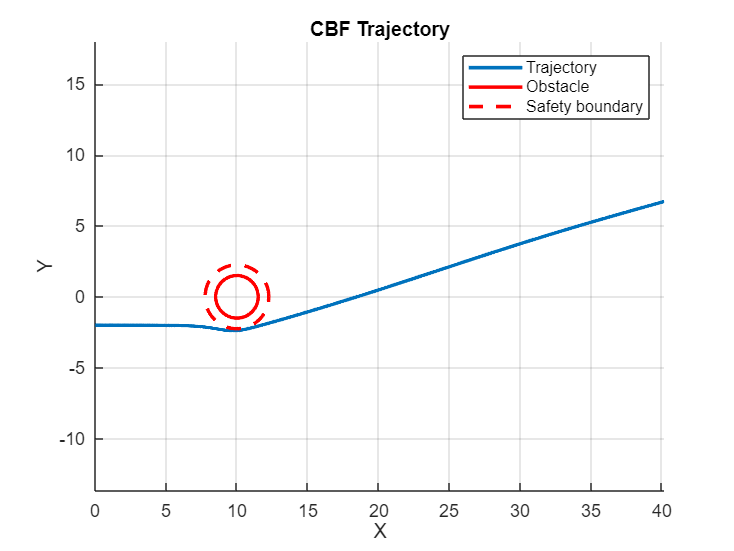

%  Aidan Fitzpatrick - ROB-GY 7863 AMR Project
%  CBF Obstacle aAvoidance Planner for Anti-Ackermann Vehicle
%  State: x = [X;Y;theta;Vx;Vy;omega] | Control: u = [F1; F2; F3; F4] (wheel longitudinal forces)


clc;
clear;
close all;





%Parameters (P)
p.m   = 700;
p.Izz = 800;
p.l   = 3.6/2;
p.b   = 2.0/2;

nu = 4; % num inputs
u_min = -2000*ones(nu,1);
u_max =  2000*ones(nu,1);

% CBF Params
cbf.k0 = 10;
cbf.k1 = 12;

obs.Xo = 10; %obstacle
obs.Yo =  0;
obs.R  =  1.5;
obs.Rs =  0.75; %safe radius

% Controlller gains
Kp = diag([2.0 2.0 4.0]);
Kd = diag([1.5 1.5 2.5]);

dt = 0.01;
T  = 16;
t  = 0:dt:T;
N  = length(t);

x = zeros(6,N);
x(:,1) = [0; -2; 0; 5; 0; 0]; %init





u_reg_log  = zeros(nu,N);
u_safe_log = zeros(nu,N);
h_log      = zeros(1,N);






opts = optimoptions('quadprog','Display','off');

for k = 1:N-1
    xk = x(:,k);

    % simple curved path
    [Vd, wd] = reference_velocity(t(k));

    u_reg = regular_controller(xk, Vd, wd, Kp, Kd, p);

    % CBF planner (QP safety)
    u_safe = cbf_planner_qp(xk, u_reg, obs, cbf, p, u_min, u_max, opts);

    xdot = full_dynamics(xk, u_safe, p);
    x(:,k+1) = xk + dt*xdot;


    
    u_reg_log(:,k)  = u_reg;
    u_safe_log(:,k) = u_safe;
    h_log(k)        = cbf_h(xk, obs);
end







figure; hold on; axis equal; grid on;
plot(x(1,:), x(2,:), 'LineWidth',2);
plot_obstacle(obs);
xlabel('X'); ylabel('Y');
title('CBF Trajectory');

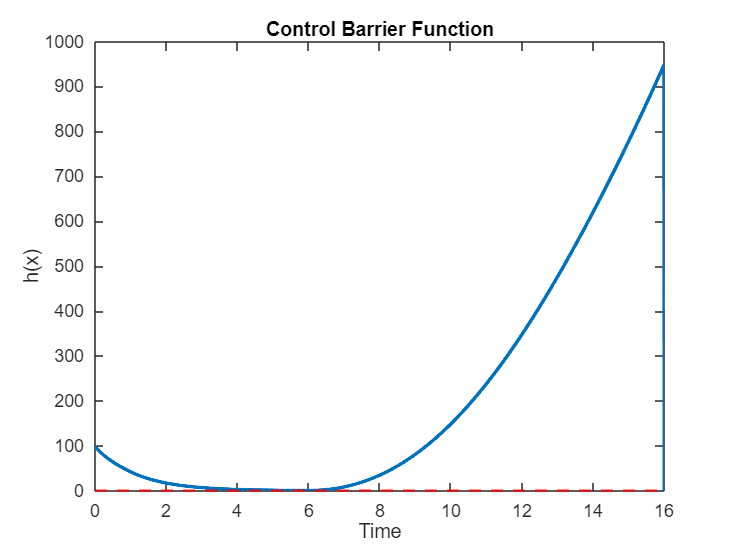


figure; grid on;
plot(t, h_log,'LineWidth',2); hold on;
yline(0,'r--','LineWidth',1.5);
xlabel('Time'); ylabel('h(x)');
title('Control Barrier Function');

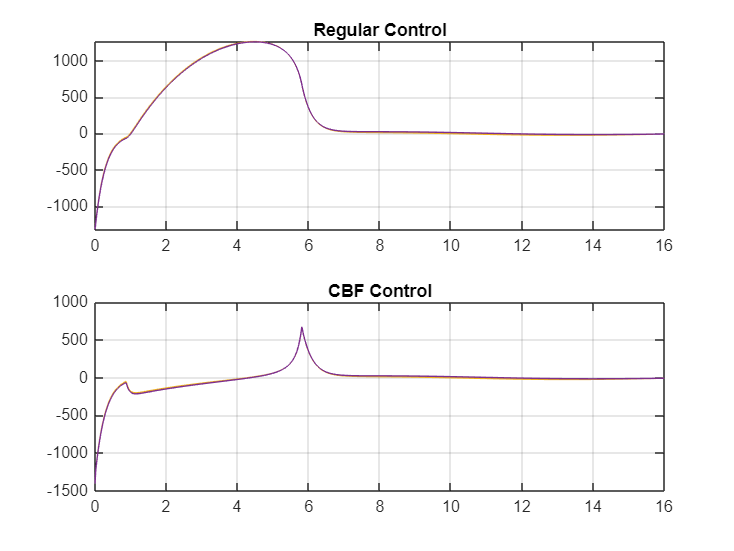


figure;
subplot(2,1,1); plot(t,u_reg_log'); title('Regular Control'); grid on;
subplot(2,1,2); plot(t,u_safe_log'); title('CBF Control'); grid on;














function xdot = full_dynamics(x,u,p)
    th = x(3);
    Vx = x(4);
    Vy = x(5);
    w = x(6);

    R = [cos(th) -sin(th); sin(th) cos(th)];
    XYdot = R*[Vx; Vy];

    [v_dot,~,~] = vehicle_dynamics_body(x,u,p);

    xdot = [XYdot(1);XYdot(2);w;v_dot];
end

function u_reg = regular_controller(x,Vd,wd,Kp,Kd,p)
    V  = x(4:6);
    Vref = [Vd;0;wd];
    e  = Vref - V;

    a_cmd = Kp*e - Kd*V;

    [~,B,f] = vehicle_dynamics_body(x,zeros(4,1),p);
    u_reg = pinv(B)*(a_cmd - f);
end

function u_safe = cbf_planner_qp(x,u_reg,obs,cbf,p,u_min,u_max,opts)

    % Compute h, h_dot because controller deals w second order
    % This is where k1 k0 come in
    X=x(1);
    Y=x(2);
    th=x(3);
    Vx=x(4);
    Vy=x(5);
    w=x(6);

    dx=X-obs.Xo;
    dy=Y-obs.Yo;

    h = dx^2+dy^2-(obs.R+obs.Rs)^2; % distance to circle w radius R

    R=[cos(th) -sin(th); sin(th) cos(th)];
    XYdot = R*[Vx;Vy];
    % deriv
    h_dot = 2*dx*XYdot(1)+2*dy*XYdot(2);

    % Dynamics
    [~,B,f] = vehicle_dynamics_body(x,zeros(4,1),p);

    Xdd0 = cos(th)*(f(1)-w*Vy)-sin(th)*(f(2)+w*Vx);
    Ydd0 = sin(th)*(f(1)-w*Vy)+cos(th)*(f(2)+w*Vx);

    Xu = cos(th)*B(1,:) - sin(th)*B(2,:);
    Yu = sin(th)*B(1,:) + cos(th)*B(2,:);

    hdd_const = 2*(XYdot(1)^2+XYdot(2)^2) + 2*dx*Xdd0 + 2*dy*Ydd0;
    hdd_u     = 2*dx*Xu + 2*dy*Yu;

    % Inequality A u <= b
    A = -hdd_u;
    b = hdd_const + cbf.k1*h_dot + cbf.k0*h;

    % QP
    H = eye(4);
    f_qp = -u_reg;

    [u_safe,~,flag] = quadprog(H,f_qp,A,b,[],[],u_min,u_max,[],opts);

    if flag <= 0
        u_safe = min(max(u_reg,u_min),u_max);
    end
end

function [v_dot,B,f] = vehicle_dynamics_body(x,u,p)
    Vx=x(4); Vy=x(5); w=x(6);
    m=p.m; I=p.Izz; b=p.b;

    f = [ w*Vy;-w*Vx;0 ];

    B = [1/m 1/m 1/m 1/m;
        0 0 0 0;
        b/I -b/I b/I -b/I];

    v_dot = f + B*u;
end

function h = cbf_h(x,obs)
    dx=x(1)-obs.Xo; dy=x(2)-obs.Yo;
    h = dx^2+dy^2-(obs.R+obs.Rs)^2;
end

function [Vd,wd] = reference_velocity(t)
    Vd = 5;
    wd = 0.2*sin(0.3*t);
end

function plot_obstacle(obs)
    th = linspace(0,2*pi,300);
    plot(obs.Xo+obs.R*cos(th),obs.Yo+obs.R*sin(th),'r','LineWidth',2);
    plot(obs.Xo+(obs.R+obs.Rs)*cos(th),obs.Yo+(obs.R+obs.Rs)*sin(th),'r--','LineWidth',2);
    legend('Trajectory','Obstacle','Safety boundary');
end

